# LAB1 - REALTIME 

% load variables in workspace of LAB0 (parameters according to motor 8)
load params_inertial_case.mat
load PID_params_LAB0.mat
load params_estimated_LAB0.mat
sens.enc.pulse2deg = 360/4096; 
load LAB1_DATA_v7.mat % i dati si sovrascrivono ATTENZIONE!
load LAB1_DATA_v8.mat

% define speed filter
fltr.wc = 2*pi*20;            % was 2*pi*50
Hws = tf([fltr.wc^2,0],[1, 2*fltr.d*fltr.wc, fltr.wc^2]);
[numHws, denHws] = tfdata(Hws,'v');

% define acc filter
fltr.wc = 2*pi*20;            % was 2*pi*50
Hwa = tf([fltr.wc^2,0],[1, 2*fltr.d*fltr.wc, fltr.wc^2]);
[numHwa, denHwa] = tfdata(Hwa,'v');

% define current filter
fltr.wc = 2*pi*20;            % was 2*pi*50
Hwsi =  tf([fltr.wc^2],[1, 2*fltr.d*fltr.wc, fltr.wc^2]);
[numHwsi, denHwsi] = tfdata(Hwsi,'v');

## 3.1 Part 1: position PID–control improvements

- Anti wind-up

- feed-foreward

% data.noawu        step response without awu       Part 1.1
% data.awu          step response with awu          Part 1.1
% data.noff         response without ff             Part 1.2
% data.ff           response with ff                Part 1.2

1. Perform the experimental tests by adopting the same methodology used for simulations, namely by following the procedure described in step 2 of Sec. 2.1:

Validate the effectiveness of the anti–windup mechanism implemented. For the test, use a step reference input with amplitude equal to 360°. Adjust the value of KW to obtain a satisfactory response (if needed). Compare the overshoot in the step response obtained by enabling or disabling the anti–windup scheme.

% open simulink model
open_system('REALTIME_PART1_antiawu.slx');

step_size = 360;
ctrl.Kw = 5/ctrl.ts5;   % 20 
ctrl.Kw=0;

% SIMULATION WITHOUT AWU
%sim('REALTIME_PART1_antiawu.slx');
data.noawu.t        = MotorData.time;
data.noawu.thl_ref  = MotorData.signals(1).values(:,1);     % reference input [deg]
data.noawu.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data.noawu.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.noawu.acc_meas = MotorData.signals(3).values;          % acc measured [rpm/s]
data.noawu.u        = MotorData.signals(4).values;          % control input  [V]

ctrl.Kw = 5/ctrl.ts5; 

% SIMULATION WITH AWU
%sim('REALTIME_PART1_antiawu.slx');
data.awu.t        = MotorData.time;
data.awu.thl_ref  = MotorData.signals(1).values(:,1);     % reference input [deg]
data.awu.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data.awu.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.awu.acc_meas = MotorData.signals(3).values;          % acc measured [rpm/s]
data.awu.u        = MotorData.signals(4).values;          % control input  [V]

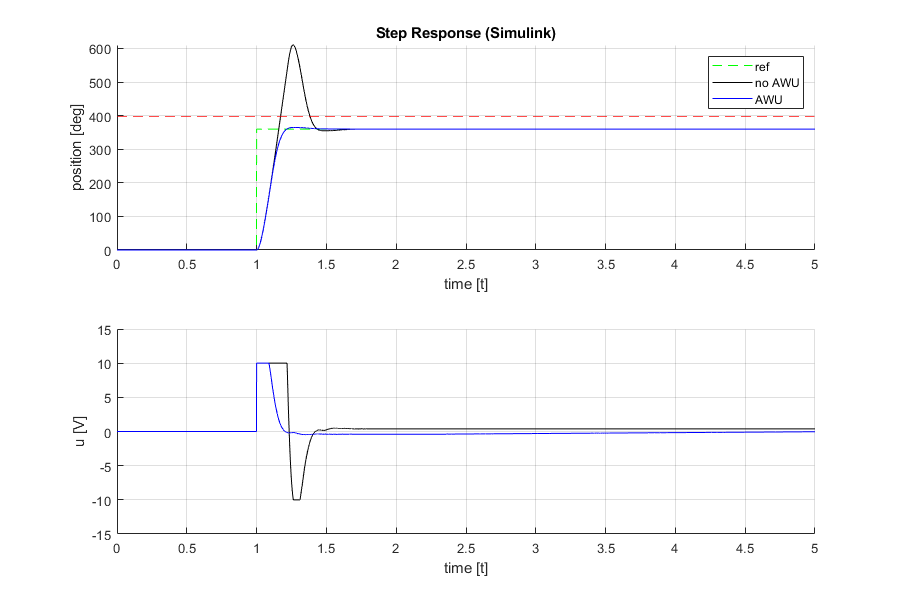

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,1,1);
hold on;
plot(data.noawu.t,data.noawu.thl_ref,'g--');
plot(data.noawu.t,data.noawu.thl_meas,'k');
plot(data.awu.t,data.awu.thl_meas,'b');
title('Step Response (Simulink)')
xlabel('time [t]');
ylabel('position [deg]');
grid on;
yline(step_size*1.1,'r--');
hold off;
legend('ref','no AWU','AWU');

subplot(2,1,2);
hold on;
plot(data.noawu.t,data.noawu.u,'k');
plot(data.awu.t,data.awu.u,'b');
xlabel('time [t]');
ylabel('u [V]');
ylim([-15,15])
grid on;
hold off;

data.noawu.stepinfo = stepinfo(data.noawu.thl_meas,data.noawu.t,'SettlingTimeThreshold',0.05);
data.awu.stepinfo   = stepinfo(data.awu.thl_meas,data.awu.t,'SettlingTimeThreshold',0.05);
stepinfo(data.noawu.thl_meas,data.noawu.t,'SettlingTimeThreshold',0.05)

ans = struct with fields:
        RiseTime: 0.1115
    SettlingTime: 1.4012
     SettlingMin: 325.7227
     SettlingMax: 610.3125
       Overshoot: 69.5313
      Undershoot: 0
            Peak: 610.3125
        PeakTime: 1.2610


stepinfo(data.awu.thl_meas,data.awu.t,'SettlingTimeThreshold',0.05)

ans = struct with fields:
        RiseTime: 0.1294
    SettlingTime: 1.1821
     SettlingMin: 324.4922
     SettlingMax: 364.8340
       Overshoot: 1.3675
      Undershoot: 0
            Peak: 364.8340
        PeakTime: 1.2570


2. Validate the feedforward compensator designed in point 3 of Sec. 2.1 on the experimental setup. Perform the experimental tests by adopting the same methodology used for simulations, namely by following the procedure described in step 4 of Sec. 2.1.

% Feedforward params
inertia_comp = gbox.N*Req*Jeq_hat /(drv.dcgain*mot.Kt);
friction_comp = Req/(drv.dcgain*mot.Kt*gbox.N);
BEMF_comp = gbox.N*mot.Ke/drv.dcgain;  

% open simulink model
open_system('REALTIME_PART1_feedforward.slx');

% SIMULATION WITHOUT FEEDFORWARD
%sim('REALTIME_PART1_feedforward.slx');
data.noff.t        = MotorData.time;
data.noff.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
data.noff.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data.noff.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
data.noff.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
data.noff.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
data.noff.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
data.noff.u        = MotorData.signals(4).values;          % control input  [V]

% SIMULATION WITH FEEDFORWARD
%sim('REALTIME_PART1_feedforward.slx');
data.ff.t        = MotorData.time;
data.ff.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
data.ff.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data.ff.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
data.ff.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
data.ff.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
data.ff.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
data.ff.u        = MotorData.signals(4).values;          % control input  [V]

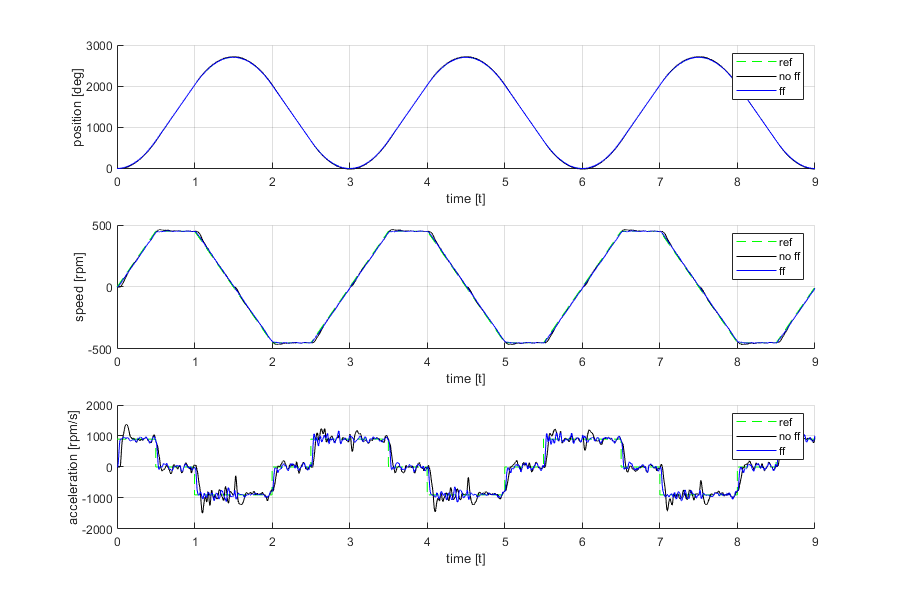

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(3,1,1);
hold on;
plot(data.noff.t,data.noff.thl_ref,'g--');
plot(data.noff.t,data.noff.thl_meas,'k');
plot(data.ff.t,data.ff.thl_meas,'b');
xlabel('time [t]');
ylabel('position [deg]');
grid on;
hold off;
legend('ref','no ff','ff');

subplot(3,1,2);
hold on;
plot(data.noff.t,data.noff.wl_ref,'g--');
plot(data.noff.t,data.noff.wl_meas,'k');
plot(data.ff.t,data.ff.wl_meas,'b');
xlabel('time [t]');
ylabel('speed [rpm]');
grid on;
hold off;
legend('ref','no ff','ff');

subplot(3,1,3);
hold on;
plot(data.noff.t,data.noff.acc_ref,'g--');
plot(data.noff.t,data.noff.acc_meas,'k');
plot(data.ff.t,data.ff.acc_meas,'b');
xlabel('time [t]');
ylabel('acceleration [rpm/s]');
grid on;
hold off;
legend('ref','no ff','ff');

ctrl.Kw=0; 

% SIMULATION WITHOUT FEEDFORWARD
%sim('REALTIME_PART1_feedforward.slx');
data.noff.noaw.t        = MotorData.time;
data.noff.noaw.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
data.noff.noaw.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data.noff.noaw.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
data.noff.noaw.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
data.noff.noaw.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
data.noff.noaw.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
data.noff.noaw.u        = MotorData.signals(4).values;          % control input  [V]

% SIMULATION WITH FEEDFORWARD
%sim('REALTIME_PART1_feedforward.slx');
data.ff.noaw.t        = MotorData.time;
data.ff.noaw.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
data.ff.noaw.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data.ff.noaw.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
data.ff.noaw.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
data.ff.noaw.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
data.ff.noaw.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
data.ff.noaw.u        = MotorData.signals(4).values;          % control input  [V]

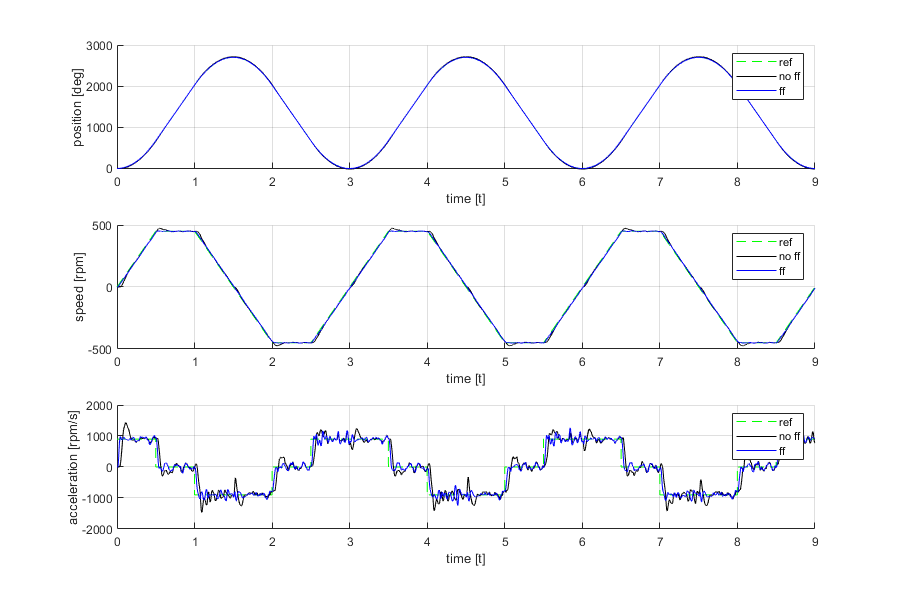

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(3,1,1);
hold on;
plot(data.noff.noaw.t,data.noff.noaw.thl_ref,'g--');
plot(data.noff.noaw.t,data.noff.noaw.thl_meas,'k');
plot(data.ff.noaw.t,data.ff.noaw.thl_meas,'b');
xlabel('time [t]');
ylabel('position [deg]');
grid on;
hold off;
legend('ref','no ff','ff');

subplot(3,1,2);
hold on;
plot(data.noff.noaw.t,data.noff.noaw.wl_ref,'g--');
plot(data.noff.noaw.t,data.noff.noaw.wl_meas,'k');
plot(data.ff.noaw.t,data.ff.noaw.wl_meas,'b');
xlabel('time [t]');
ylabel('speed [rpm]');
grid on;
hold off;
legend('ref','no ff','ff');

subplot(3,1,3);
hold on;
plot(data.noff.noaw.t,data.noff.noaw.acc_ref,'g--');
plot(data.noff.noaw.t,data.noff.noaw.acc_meas,'k');
plot(data.ff.noaw.t,data.ff.noaw.acc_meas,'b');
xlabel('time [t]');
ylabel('acceleration [rpm/s]');
grid on;
hold off;
legend('ref','no ff','ff');

## Part 2: position state–space control design

-  Nominal Tracking Design

-  Robust Tracking Design

-  Robust Tracking Design with the internal model principle

### 1) Nominal Tracking Design

Beq = Beq_hat;                           % mot.B + mld.B/gbox.N^2;    
Jeq = Jeq_hat;
model.km = (drv.dcgain*mot.Kt)/(Req*Beq + mot.Kt*mot.Ke);
model.Tm = (Req*Jeq)/(Req*Beq + mot.Kt*mot.Ke);

%   non-encapsulated SS data
A = [0, 1; 0, -1/model.Tm];
B = [0; model.km/(gbox.N*model.Tm)];
C = [1, 0];
D = 0;

%   SS data encapulated in a SS object
sys = ss(A, B, C, D);

%compute N_x, N_u
S = [A,B;C,0];
b=[0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);


% define H1 filter
H1.wc = 2*pi*50;   
H1.d = 1/sqrt(2);
H1s = tf([H1.wc^2,0],[1, 2*H1.d*H1.wc, H1.wc^2]);
[numH1, denH1] = tfdata(H1s,'v');

%specs
spec.ts5    = 0.15;         % Settling-time
spec.Mp     = 0.1;          % Overshoot
spec.damp   = log(1/spec.Mp) / (sqrt(pi^2+(log(1/spec.Mp))^2));
spec.wn   = 3 / (spec.damp*spec.ts5);

%poles to place
Ts = tf([spec.wn^2],[1, 2*spec.damp*spec.wn,spec.wn^2]);
p=pole(Ts);

%Compute feedback matrix
K=place(A,B,p);

open_system('REALTIME_PART2_nominal.slx');

step_size = 40;

%sim('REALTIME_PART2_nominal');
data.nominal.step1.t        = MotorData.time;                       % reference angle input [deg]
data.nominal.step1.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.nominal.step1.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.nominal.step1.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.nominal.step1.u        = MotorData.signals(3).values;          % control input [V]

step_size = 70;

%sim('REALTIME_PART2_nominal');
data.nominal.step2.t        = MotorData.time;                       % reference angle input [deg]
data.nominal.step2.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.nominal.step2.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.nominal.step2.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.nominal.step2.u        = MotorData.signals(3).values;          % control input [V]

step_size = 120;

%sim('REALTIME_PART2_nominal');
data.nominal.step3.t        = MotorData.time;                       % reference angle input [deg]
data.nominal.step3.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.nominal.step3.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.nominal.step3.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.nominal.step3.u        = MotorData.signals(3).values;          % control input [V]

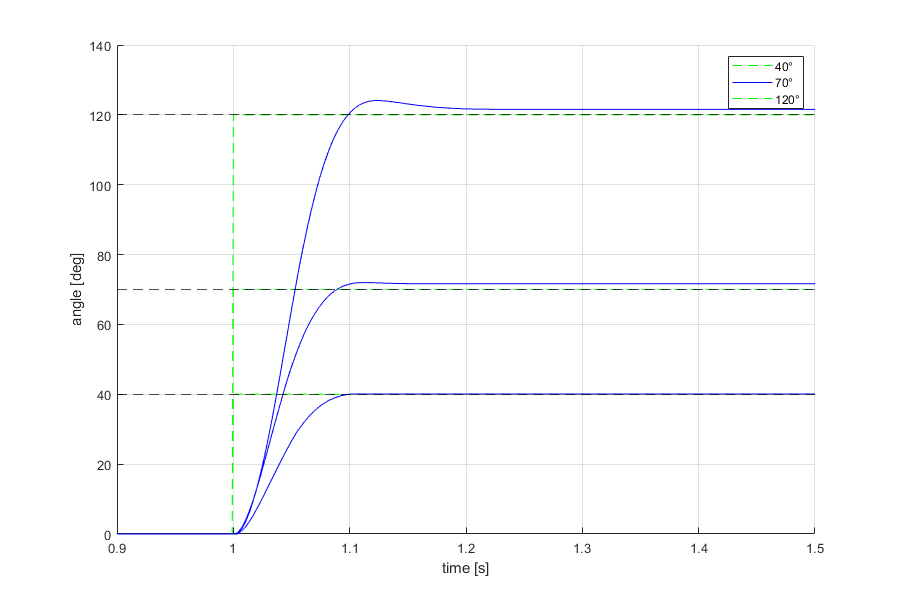

figure('Renderer', 'painters', 'Position', [10 10 900 600])


hold on;
plot(data.nominal.step1.t,data.nominal.step1.thl_ref,'g--');
plot(data.nominal.step1.t,data.nominal.step1.thl_meas,'b');
plot(data.nominal.step2.t,data.nominal.step2.thl_ref,'g--');
plot(data.nominal.step2.t,data.nominal.step2.thl_meas,'b');
plot(data.nominal.step3.t,data.nominal.step3.thl_ref,'g--');
plot(data.nominal.step3.t,data.nominal.step3.thl_meas,'b');

yline(40,'k--')
yline(70,'k--')
yline(120,'k--')
hold off;
legend('40°','70°','120°');
xlabel('time [s]');
ylabel('angle [deg]');
grid on
xlim([0.9,1.5]);

data.nominal.step1.stepinfo = stepinfo(data.nominal.step1.thl_meas,data.nominal.step1.t,'SettlingTimeThreshold',0.05);
data.nominal.step2.stepinfo = stepinfo(data.nominal.step2.thl_meas,data.nominal.step2.t,'SettlingTimeThreshold',0.05);
data.nominal.step3.stepinfo = stepinfo(data.nominal.step3.thl_meas,data.nominal.step3.t,'SettlingTimeThreshold',0.05);

### 2)  Robust Tracking Design;

%poles
sigma=-spec.damp*spec.wn;
omega_d=spec.wn*sqrt(1-spec.damp^2);

p1 = [sigma+omega_d*j , sigma-omega_d*j , sigma ];
p2 = [sigma , sigma , sigma ];
p3 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 2*sigma ];
p4 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 3*sigma ];

%space model with augmented state
zer = zeros(2,1);
Ae=[0 C; zer A];
Be=[0; B];
Ce=[0 C];

ctrl.Kw = 0;

open_system('REALTIME_PART2_robust.slx');

% select p2 (it is the best)
Ke = acker(Ae,Be,p4);
Ki = Ke(1);
K2 = [Ke(2) Ke(3)];

step_size = 40;

%sim('REALTIME_PART2_robust');
data.robust.step1.t        = MotorData.time;                       % reference angle input [deg]
data.robust.step1.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.robust.step1.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.robust.step1.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.robust.step1.u        = MotorData.signals(3).values;          % control input [V]
data.robust.step1.u_nosat  = ControllerData.signals(1).values;     % PID no sat
data.robust.step1.u_sat    = ControllerData.signals(2).values;     % PID  sat

step_size = 70;

%sim('REALTIME_PART2_robust');
data.robust.step2.t        = MotorData.time;                       % reference angle input [deg]
data.robust.step2.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.robust.step2.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.robust.step2.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.robust.step2.u        = MotorData.signals(3).values;          % control input [V]
data.robust.step2.u_nosat  = ControllerData.signals(1).values;     % PID no sat
data.robust.step2.u_sat    = ControllerData.signals(2).values;     % PID  sat

step_size = 120;

%sim('REALTIME_PART2_robust');
data.robust.step3.t        = MotorData.time;                       % reference angle input [deg]
data.robust.step3.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.robust.step3.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.robust.step3.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.robust.step3.u        = MotorData.signals(3).values;          % control input [V]
data.robust.step3.u_nosat  = ControllerData.signals(1).values;     % PID no sat
data.robust.step3.u_sat    = ControllerData.signals(2).values;     % PID  sat

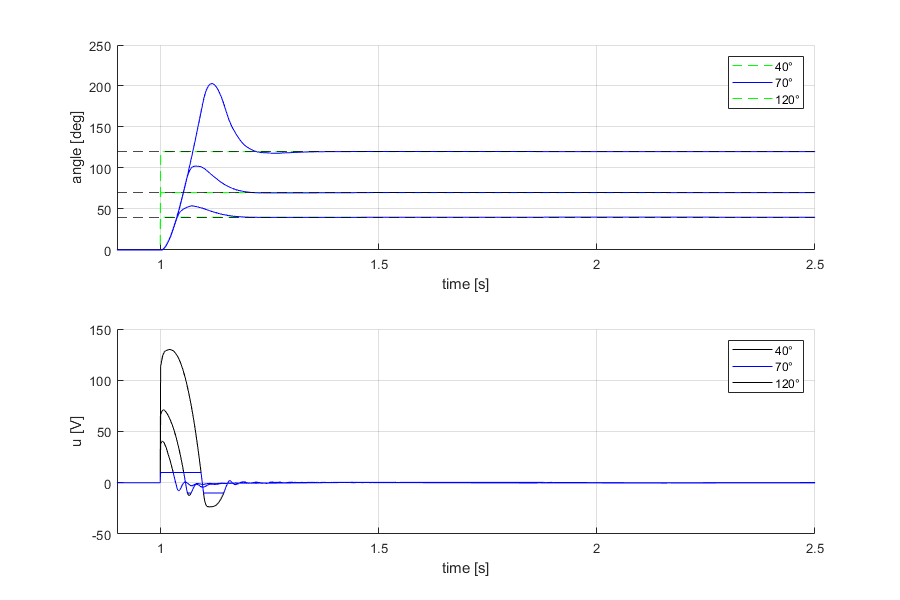

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2,1,1);

hold on;
plot(data.robust.step1.t,data.robust.step1.thl_ref,'g--');
plot(data.robust.step1.t,data.robust.step1.thl_meas,'b');
plot(data.robust.step2.t,data.robust.step2.thl_ref,'g--');
plot(data.robust.step2.t,data.robust.step2.thl_meas,'b');
plot(data.robust.step3.t,data.robust.step3.thl_ref,'g--');
plot(data.robust.step3.t,data.robust.step3.thl_meas,'b');

yline(40,'k--')
yline(70,'k--')
yline(120,'k--')
hold off;
legend('40°','70°','120°');
xlabel('time [s]');
ylabel('angle [deg]');
grid on
xlim([0.9,2.5]);

subplot(2,1,2);

hold on;
plot(data.robust.step1.t,data.robust.step1.u_nosat,'k');
plot(data.robust.step1.t,data.robust.step1.u_sat,'b');
plot(data.robust.step2.t,data.robust.step2.u_nosat,'k');
plot(data.robust.step2.t,data.robust.step2.u_sat,'b');
plot(data.robust.step3.t,data.robust.step3.u_nosat,'k');
plot(data.robust.step3.t,data.robust.step3.u_sat,'b');

hold off;
legend('40°','70°','120°');
xlabel('time [s]');
ylabel('u [V]');
grid on
xlim([0.9,2.5]);

data.robust.step1.stepinfo = stepinfo(data.robust.step1.thl_meas,data.robust.step1.t,'SettlingTimeThreshold',0.05);
data.robust.step2.stepinfo = stepinfo(data.robust.step2.thl_meas,data.robust.step2.t,'SettlingTimeThreshold',0.05);
data.robust.step3.stepinfo = stepinfo(data.robust.step3.thl_meas,data.robust.step3.t,'SettlingTimeThreshold',0.05);

## ANTI WIND UP

ctrl.Kw = 1;%5/ctrl.ts5

step_size = 40;

%sim('REALTIME_PART2_robust');
data.robust.AWU.step1.t        = MotorData.time;                       % reference angle input [deg]
data.robust.AWU.step1.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.robust.AWU.step1.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.robust.AWU.step1.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.robust.AWU.step1.u        = MotorData.signals(3).values;          % control input [V]
data.robust.AWU.step1.u_nosat  = ControllerData.signals(1).values;     % PID no sat
data.robust.AWU.step1.u_sat    = ControllerData.signals(2).values;     % PID  sat

step_size = 70;

%sim('REALTIME_PART2_robust');
data.robust.AWU.step2.t        = MotorData.time;                       % reference angle input [deg]
data.robust.AWU.step2.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.robust.AWU.step2.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.robust.AWU.step2.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.robust.AWU.step2.u        = MotorData.signals(3).values;          % control input [V]
data.robust.AWU.step2.u_nosat  = ControllerData.signals(1).values;     % PID no sat
data.robust.AWU.step2.u_sat    = ControllerData.signals(2).values;     % PID  sat

step_size = 120;

%sim('REALTIME_PART2_robust');
data.robust.AWU.step3.t        = MotorData.time;                       % reference angle input [deg]
data.robust.AWU.step3.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
data.robust.AWU.step3.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
data.robust.AWU.step3.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
data.robust.AWU.step3.u        = MotorData.signals(3).values;          % control input [V]
data.robust.AWU.step3.u_nosat  = ControllerData.signals(1).values;     % PID no sat
data.robust.AWU.step3.u_sat    = ControllerData.signals(2).values;     % PID  sat

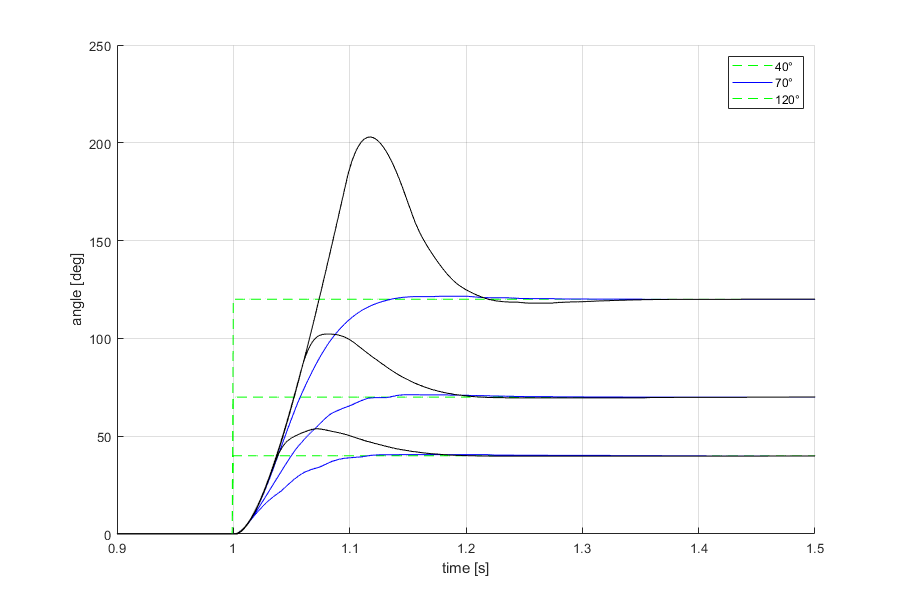

figure('Renderer', 'painters', 'Position', [10 10 900 600])



hold on;
plot(data.robust.AWU.step1.t,data.robust.AWU.step1.thl_ref,'g--');
plot(data.robust.AWU.step1.t,data.robust.AWU.step1.thl_meas,'b');
plot(data.robust.AWU.step2.t,data.robust.AWU.step2.thl_ref,'g--');
plot(data.robust.AWU.step2.t,data.robust.AWU.step2.thl_meas,'b');
plot(data.robust.AWU.step3.t,data.robust.AWU.step3.thl_ref,'g--');
plot(data.robust.AWU.step3.t,data.robust.AWU.step3.thl_meas,'b');

plot(data.robust.step1.t,data.robust.step1.thl_meas,'k');

plot(data.robust.step2.t,data.robust.step2.thl_meas,'k');

plot(data.robust.step3.t,data.robust.step3.thl_meas,'k');


hold off;
legend('40°','70°','120°');
xlabel('time [s]');
ylabel('angle [deg]');
grid on
xlim([0.9,1.5]);


data.robust.AWU.step1.stepinfo = stepinfo(data.robust.AWU.step1.thl_meas,data.robust.AWU.step1.t,'SettlingTimeThreshold',0.05);
data.robust.AWU.step2.stepinfo = stepinfo(data.robust.AWU.step2.thl_meas,data.robust.AWU.step2.t,'SettlingTimeThreshold',0.05);
data.robust.AWU.step3.stepinfo = stepinfo(data.robust.AWU.step3.thl_meas,data.robust.AWU.step3.t,'SettlingTimeThreshold',0.05);

## Robust Tracking Design with the internal model principle

%poles
pa=spec.wn*exp(j*(-pi+pi/4));
pb=spec.wn*exp(j*(-pi-pi/4));
pc=spec.wn*exp(j*(-pi+pi/6));
pd=spec.wn*exp(j*(-pi-pi/6));
pe=-spec.wn;
p=[pa pb pc pd pe];

Tr = 0.5;
w0= 2*pi/Tr;

%compute Az, Bz of the extended model in error-space
Ar=[0,1,0;0,0,1;0,-w0^2, 0];
zer=zeros(2,3);
colonna = [0,0;0,0; C];
Az= [Ar colonna;zer A];
Bz=[0;0;0;B];
Kz=acker(Az,Bz,p);

open_system('REALTIME_PART2_errorspace.slx');

Ar=30;

%sim('REALTIME_PART2_errorspace');

data.errorspace.amp1.t          = MotorData.time;
data.errorspace.amp1.thl_ref    = MotorData.signals(1).values(:,1);
data.errorspace.amp1.thl_meas   = MotorData.signals(1).values(:,2);
data.errorspace.amp1.wl_meas    = MotorData.signals(2).values;
data.errorspace.amp1.e          = MotorData.signals(3).values;
data.errorspace.amp1.u          = squeeze(MotorData.signals(4).values);

Ar=60;

%sim('REALTIME_PART2_errorspace');
data.errorspace.amp2.t          = MotorData.time;
data.errorspace.amp2.thl_ref    = MotorData.signals(1).values(:,1);
data.errorspace.amp2.thl_meas   = MotorData.signals(1).values(:,2);
data.errorspace.amp2.wl_meas    = MotorData.signals(2).values;
data.errorspace.amp2.e          = MotorData.signals(3).values;
data.errorspace.amp2.u          = squeeze(MotorData.signals(4).values);

Ar=90;

%sim('REALTIME_PART2_errorspace');
data.errorspace.amp3.t          = MotorData.time;
data.errorspace.amp3.thl_ref    = MotorData.signals(1).values(:,1);
data.errorspace.amp3.thl_meas   = MotorData.signals(1).values(:,2);
data.errorspace.amp3.wl_meas    = MotorData.signals(2).values;
data.errorspace.amp3.e          = MotorData.signals(3).values;
data.errorspace.amp3.u          = squeeze(MotorData.signals(4).values);

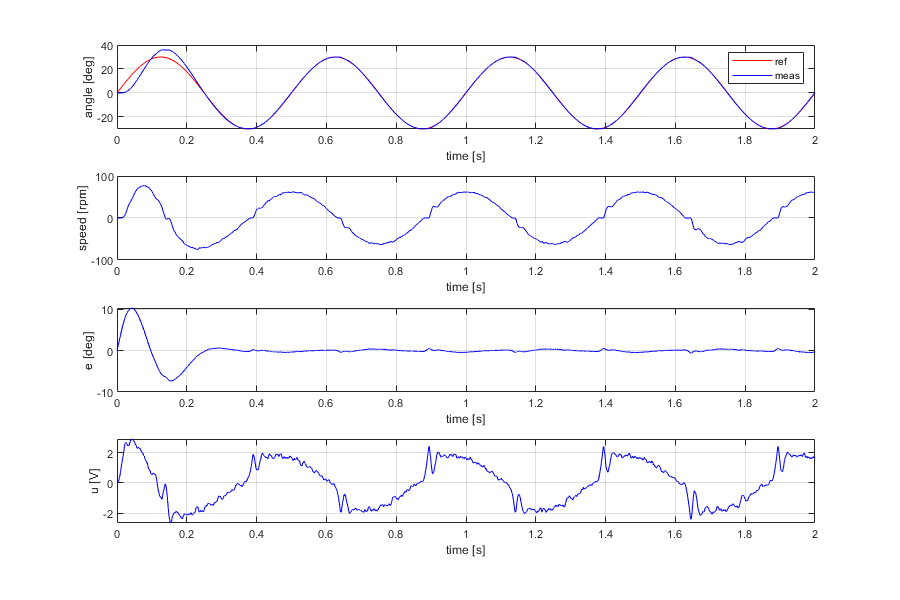

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,1,1);
plot(data.errorspace.amp1.t,data.errorspace.amp1.thl_ref,'r',data.errorspace.amp1.t,data.errorspace.amp1.thl_meas,'b');
legend('ref','meas');
xlabel('time [s]');
ylabel('angle [deg]');
grid on
xlim([0,2]);

subplot(4,1,2);
plot(data.errorspace.amp1.t,data.errorspace.amp1.wl_meas,'b');
xlabel('time [s]');
ylabel('speed [rpm]');
grid on
xlim([0,2]);

subplot(4,1,3);
plot(data.errorspace.amp1.t,data.errorspace.amp1.e,'b');
xlabel('time [s]');
ylabel('e [deg]');
grid on
xlim([0,2]);

subplot(4,1,4);
plot(data.errorspace.amp1.t,data.errorspace.amp1.u,'b');
xlabel('time [s]');
ylabel('u [V]');
grid on
xlim([0,2]);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,1,1);
plot(data.errorspace.amp2.t,data.errorspace.amp2.thl_ref,'r',data.errorspace.amp2.t,data.errorspace.amp2.thl_meas,'b');
legend('ref','meas');
xlabel('time [s]');
ylabel('angle [deg]');

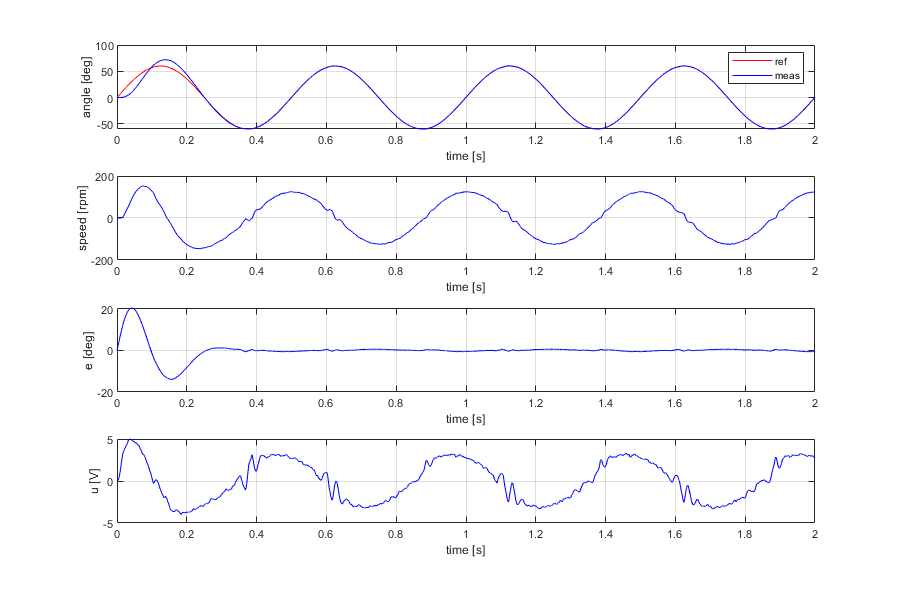

grid on
xlim([0,2]);
subplot(4,1,2);
plot(data.errorspace.amp2.t,data.errorspace.amp2.wl_meas,'b');
xlabel('time [s]');
ylabel('speed [rpm]');
grid on
xlim([0,2]);
subplot(4,1,3);
plot(data.errorspace.amp2.t,data.errorspace.amp2.e,'b');
xlabel('time [s]');
ylabel('e [deg]');
grid on
xlim([0,2]);
subplot(4,1,4);
plot(data.errorspace.amp2.t,data.errorspace.amp2.u,'b');
xlabel('time [s]');
ylabel('u [V]');
grid on
xlim([0,2]);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,1,1);
plot(data.errorspace.amp3.t,data.errorspace.amp3.thl_ref,'r',data.errorspace.amp3.t,data.errorspace.amp3.thl_meas,'b');
legend('ref','meas');
xlabel('time [s]');
ylabel('angle [deg]');

grid on
xlim([0,2]);
subplot(4,1,2);
plot(data.errorspace.amp3.t,data.errorspace.amp3.wl_meas,'b');
xlabel('time [s]');
ylabel('speed [rpm]');
grid on
xlim([0,2]);
subplot(4,1,3);
plot(data.errorspace.amp3.t,data.errorspace.amp3.e,'b');
xlabel('time [s]');
ylabel('e [deg]');
grid on
xlim([0,2]);
subplot(4,1,4);
plot(data.errorspace.amp3.t,data.errorspace.amp3.u,'b');
xlabel('time [s]');
ylabel('u [V]');
grid on
xlim([0,2]);

## STEP INPUT

step_size = 40;

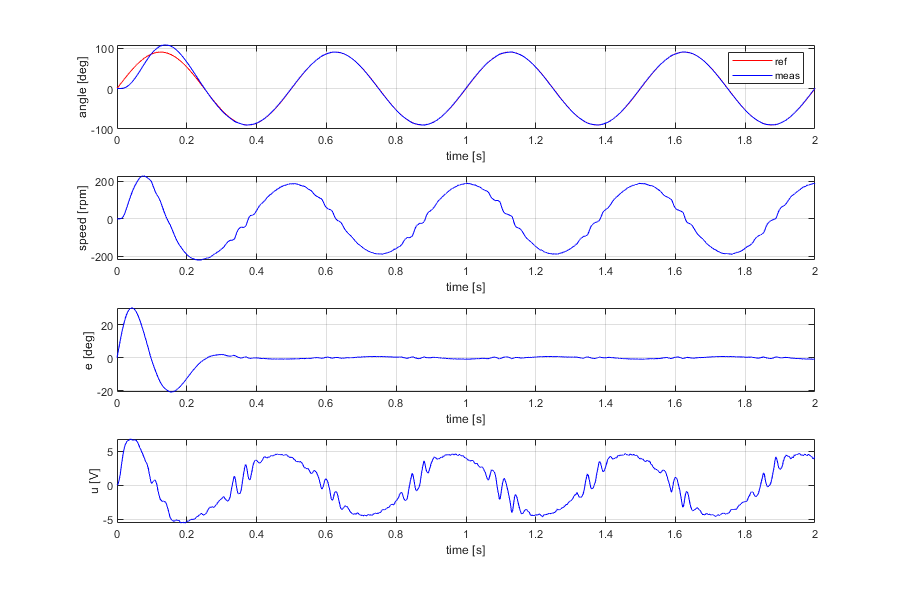

data.errorspace.step.t          = MotorData.time;
data.errorspace.step.thl_ref    = MotorData.signals(1).values(:,1);
data.errorspace.step.thl_meas   = MotorData.signals(1).values(:,2);
data.errorspace.step.wl_meas    = MotorData.signals(2).values;
data.errorspace.step.e          = MotorData.signals(3).values;
data.errorspace.step.u          = squeeze(MotorData.signals(4).values);


figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,1,1);
plot(data.errorspace.step.t,data.errorspace.step.thl_ref,'r',data.errorspace.step.t,data.errorspace.step.thl_meas,'b');
legend('ref','meas');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

subplot(4,1,2);
plot(data.errorspace.step.t,data.errorspace.step.wl_meas,'b');
xlabel('time [s]');
ylabel('speed [rpm]');
grid on

subplot(4,1,3);
plot(data.errorspace.step.t,data.errorspace.step.e,'b');
xlabel('time [s]');
ylabel('e [deg]');
grid on

subplot(4,1,4);
plot(data.errorspace.step.t,data.errorspace.step.u,'b');
xlabel('time [s]');
ylabel('u [V]');
grid on

## (BONUS) Extended state-estimator method

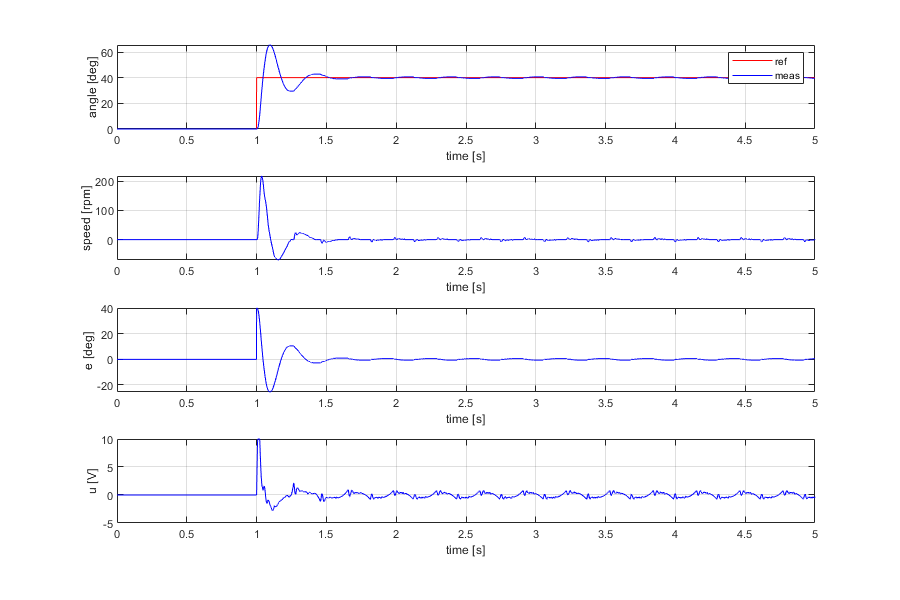

%"controller" eigenvalues and "estimator" eigenvalues
pc1=-spec.damp*spec.wn + j*spec.wn*sqrt(1-spec.damp^2);
pc2=-spec.damp*spec.wn - j*spec.wn*sqrt(1-spec.damp^2);
pc = [pc1 , pc2];

pe1=2*spec.wn*exp(j*(-pi+pi/3));
pe2 = conj(pe1);
pe3=2*spec.wn*exp(j*(-pi+pi/6));
pe4 = conj(pe3);
pe5=-2*spec.wn;

pe =[pe1 pe2 pe3 pe4 pe5];

% reference
T = [0.15 0.25 0.5 1];
Tr = 0.5;
w0 = 2*pi/Tr;
Ar = 30;

% Define system
Ap = [0 1 0 ; 0 0 1 ; 0 -w0^2 0];
Cp = [1 0 0];
A = [0, 1; 0, -1/model.Tm];
B = [0; model.km/(gbox.N*model.Tm)];
C = [1, 0];
D = 0;
zer = zeros(3,2);
BCp = B*Cp;

Ae = [Ap , zer;
      BCp , A ];
Be = [0 ; 0 ; 0 ; B ];
Ce = [0 , 0 , 0 , C];
K3 = place(A,B,pc);
Le = place(Ae.',Ce.',pe).';

Aest = Ae - Le*Ce;
Best = [ Be Le];
Cest = eye(5);
Dest = zeros(5,2);

% 9.6: simulation with 30 deg sinusoidal, Tr = 0.5;

Ar = 30;
Tr = 0.5;

%sim('robust_tracking_extended_estimator.slx');

data.extended.t          = MotorData.time;
data.extended.thl_ref    = MotorData.signals(1).values(:,1);
data.extended.thl_meas   = squeeze(MotorData.signals(1).values(:,2));
data.extended.wl_meas    = squeeze(MotorData.signals(2).values);
data.extended.u          = squeeze(MotorData.signals(3).values);
data.extended.thl_err    = squeeze(MotorData.signals(4).values);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,1,1);
plot(data.extended.t,data.extended.thl_ref,'r',data.extended.t,data.extended.thl_meas,'b');
legend('ref','meas');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

subplot(4,1,2);
plot(data.extended.t,data.extended.wl_meas,'b');
xlabel('time [s]');
ylabel('speed [rpm]');
grid on

subplot(4,1,3);
plot(data.extended.t,data.extended.u,'b');
xlabel('time [s]');
ylabel('u [V]');
grid on

subplot(4,1,4);
plot(data.extended.t,data.extended.thl_err,'b');
xlabel('time [s]');
ylabel('error [deg]');
grid on

data.extended.step.t          = MotorData.time;
data.extended.step.thl_ref    = MotorData.signals(1).values(:,1);
data.extended.step.thl_meas   = squeeze(MotorData.signals(1).values(:,2));
data.extended.step.wl_meas    = squeeze(MotorData.signals(2).values);
data.extended.step.u          = squeeze(MotorData.signals(3).values);
data.extended.step.thl_err    = squeeze(MotorData.signals(4).values);

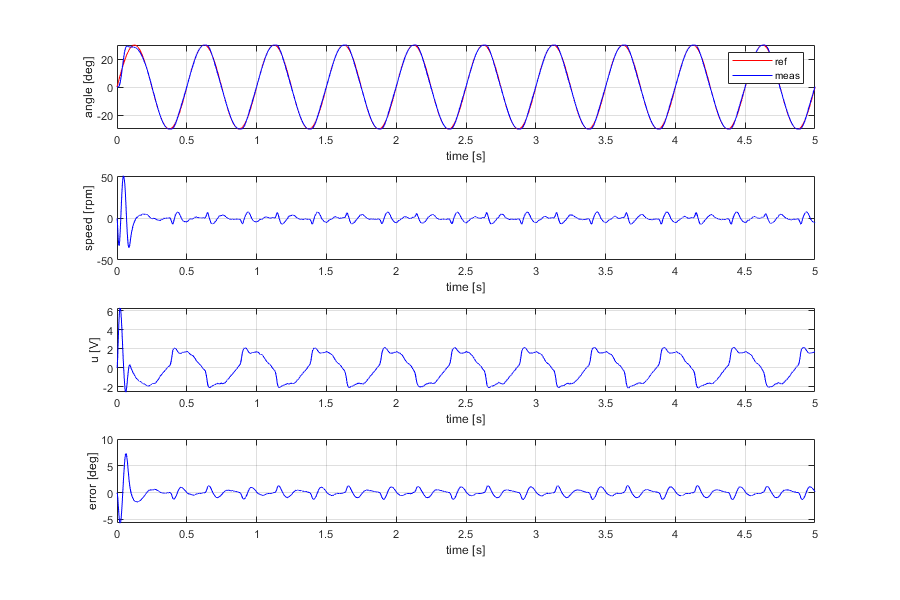

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,1,1);
plot(data.extended.step.t,data.extended.step.thl_ref,'r',data.extended.step.t,data.extended.step.thl_meas,'b');
legend('ref','meas');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

subplot(4,1,2);
plot(data.extended.step.t,data.extended.step.wl_meas,'b');

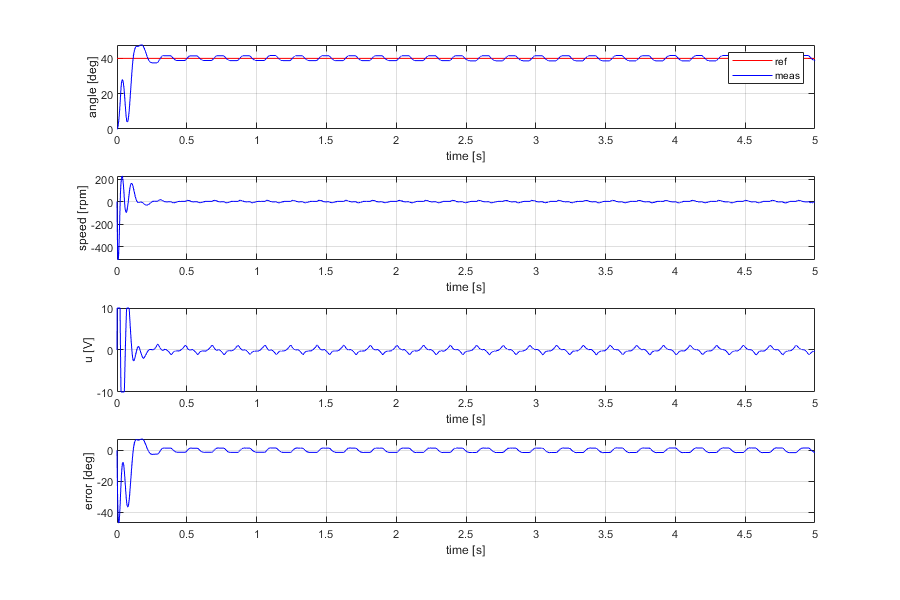

xlabel('time [s]');
ylabel('speed [rpm]');
grid on

subplot(4,1,3);
plot(data.extended.step.t,data.extended.step.u,'b');
xlabel('time [s]');
ylabel('u [V]');
grid on

subplot(4,1,4);
plot(data.extended.step.t,data.extended.step.thl_err,'b');
xlabel('time [s]');
ylabel('error [deg]');
grid on